# Ordinary DIfferential Equations

## Symbolic solution of differential equations

MATLAB knows how to solve differential equations analytically if it has `symbolic toolbox` installed. The command `dsolve` is an analytic solver.

Here we solve the Initial Value Problem (IVP) $y' = t - y$, $y(0) = 1$, which is easily solved.

syms y(t)

sol1 = dsolve(diff(y, t) == t - y, y(0) == 1)

$$sol1 = t+2\,{\mathrm{e}}^{-t}-1$$

Now the analytic solution is difficult although the problem seems to change only slightly.

sol2 = dsolve(diff(y, t) == t - y^2, y(0) == 1)

$$sol2 = \begin{array}{l} \frac{\text{airy}\left(3,t\right)-\frac{\text{airy}\left(1,t\right)\,\sigma_{1}}{\sigma_{2}}}{\text{airy}\left(2,t\right)-\frac{\text{airy}\left(0,t\right)\,\sigma_{1}}{\sigma_{2}}}\\ \mathrm{where}\\ \sigma_{1}=2\,\pi \,3^{2/3}-3\,\sqrt{3}\,{\Gamma (\frac{2}{3})}^{2}\\ \sigma_{2}=2\,\pi \,3^{1/6}+3\,{\Gamma (\frac{2}{3})}^{2} \end{array}$$

Now `dsolve` can't solve the IVP. Therefore it is time for us to examine numerical solvers.

sol3 = dsolve(diff(y, t) == t - y^3, y(0) == 1)

 
sol3 =
 
[ empty sym ]
 


## Numerical solutions of differential equations

Matlab's numerical solvers solve differential equations of the form $y' = f(t, y)$, where $y$ and $y'$ are vectors. The first argument to all the solvers is a function handle to the function $f$.

We solve the difficult one from above using the solver `ode45`.

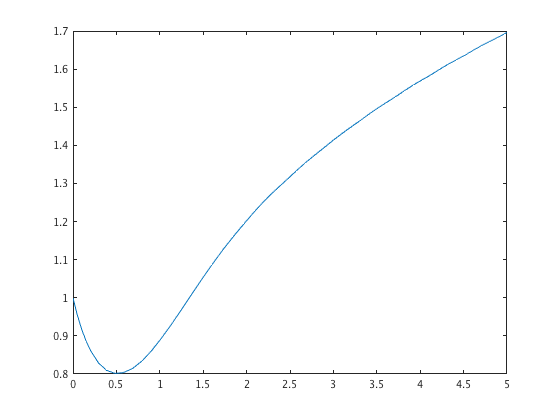

f = @(t, y) t - y^3;
[t, y] = ode45(f, [0, 5], 1);
plot(t, y);

Here we solve the system


$$y_1' = y_2y_3$$



$$y_2' = -y_1 y_3$$


    
$$y_3' = -0.5 y_1 y_2$$


with the imitial conditions $y_1(0) = 0$, $y_2(0) = 1$, $y_3(0) = 1$.

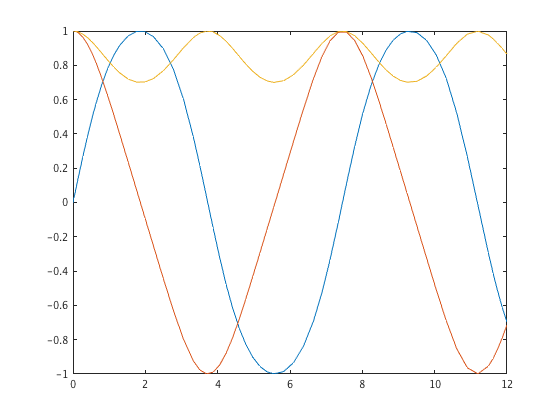

ff = @(t, y) [y(2)*y(3); -y(1)*y(3); -0.51*y(1)*y(2)];
[t, y] = ode45(ff, [0,12], [0;1;1]);
plot(t, y);

3D plot of the solution curve.

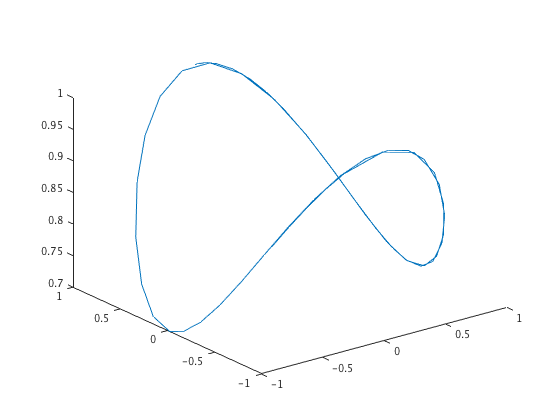

plot3(y(:,1), y(:,2), y(:,3))

A differential equation of order $n$ may be reformulated into $n$ first order differential equations. When solving the problem $z'' - 2(1 - z^2)z' + z = 0$ we introduce new variables $y_1$ and $y_2$ as follows: $y_1 = z$, $y_2 = z'$, which implies that


$$y_1' = y_2$$



$$y_2' = 2(1 - y_1^2)y_2 - y_1$$


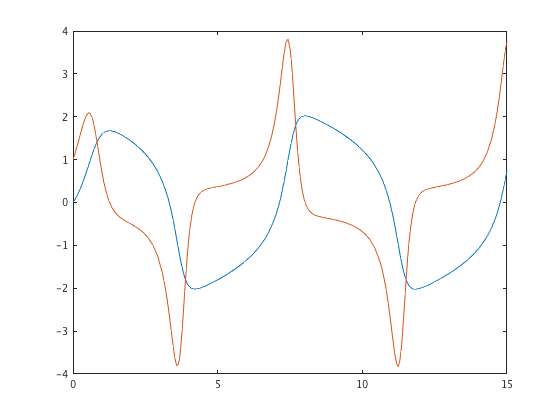

vdp = @(t, y) [y(2); 2*(1-y(1)^2)*y(2)-y(1)];
[t, y] = ode45(vdp, [0,15], [0;1]);
plot(t, y);

A phase plane (or state space) plot of the solution.

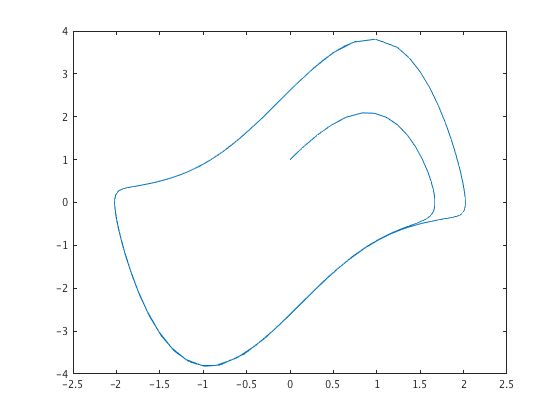

plot(y(:, 1), y(:, 2))

Notice that points are not uniformly distributed. `ode45` needs more points where the solution changes faster.

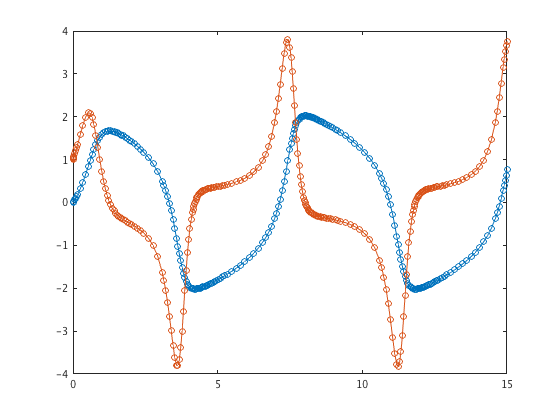

plot(t, y, 'o-');

## Solution at fixed times

In the previous example the second argument for `ode45` was the interval where the DE is to be solved. If we give a vector with more than two points instead, then `ode45` will solve the DE in these points. Do you notice the difference?

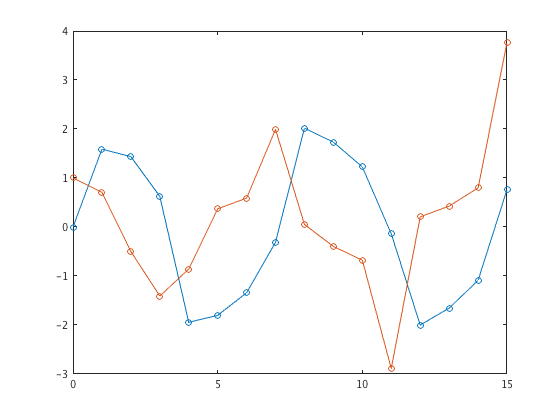

[t, y] = ode45(vdp, 0:15, [0;1]);
plot(t, y, 'o-');

## Solution as a structure

Using a single output argument returns the solution as a struct.

sol = ode45(vdp, [0,15], [0;1])

sol = struct with fields:
     solver: 'ode45'
    extdata: [1×1 struct]
          x: [1×61 double]
          y: [2×61 double]
      stats: [1×1 struct]
      idata: [1×1 struct]


sol.extdata

ans = struct with fields:
      odefun: @(t,y)[y(2);2*(1-y(1)^2)*y(2)-y(1)]
     options: []
    varargin: {}


sol.stats

ans = struct with fields:
     nsteps: 60
    nfailed: 14
    nfevals: 445


sol.idata

ans = struct with fields:
               f3d: [2×7×61 double]
    idxNonNegative: []


Using the struct it is easy to define at which points the solution will be evaluated. Here `deval` evaluates the solution at the points in the vector `t`.

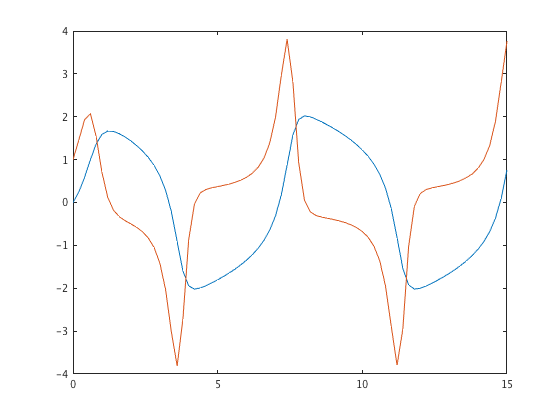

t = 0:0.2:15;
plot(t, deval(t,sol));

## Options

The solver accepts a number of options. Here the relative and absolute tolerances are set. The solver options are set by the `odeset` function. The solver options are given as the fourth parameter of the solver function call.

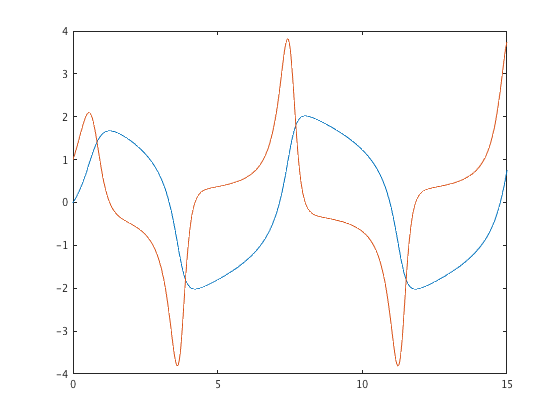

op = odeset('RelTol', 1e-5, 'AbsTol', [1e-6;1e-7]);
[t, y] = ode45(vdp, [0,15], [0;1], op);
plot(t, y);

## Parameters in the equation

The equation can have parameters. Here we have one parameter `mu` as a third argument of `vdpparams`. We pass to the solver an anonymous function which calls `vdpparams` with a fixed value as the third argument.

vdpparams = @(t, y, mu) [y(2); mu*(1-y(1)^2)*y(2)-y(1)];
[t, y] = ode45(@(t,y)vdpparams(t,y,2), [0,15],[0;1], op);
plot(t,y);

With `mu` value of 2 `ode45` has no problems, but setting `mu = 1000` some problems occur. The DE has become stiff. Stiff problems are often characterized by vastly different times scales. There is a rapidly changing component (which we are not interested in) and a slower changing component (which we are interested in). Yet the step size is forced to be small by the rapid component although the slow component would allow larger step size.

tic;
[t, y] = ode45(@(t,y)vdpparams(t,y,1000),[0,100],[0;1]);
toc

Elapsed time is 6.751041 seconds.


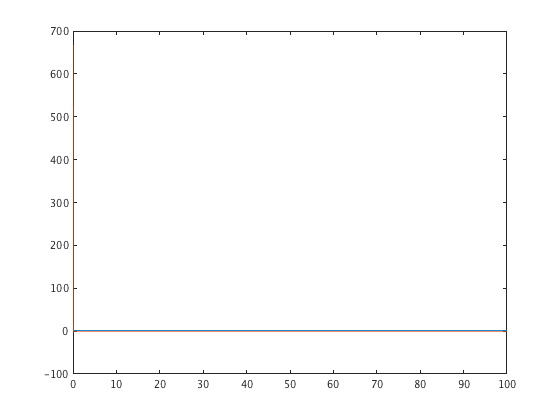

plot(t, y);

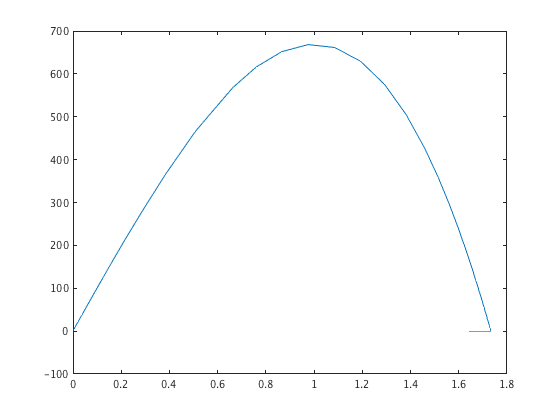

plot(y(:,1), y(:,2))

MATLAB has solvers also for stiff problems, for example `ode15s` (s is for stiff). A somewhat flippant definition of a stiff problem is: "A DE is stiff if it can be solved better with a stiff solver than a nonstiff solver".

tic;
[t, y] = ode15s(@(t,y)vdpparams(t,y,1000),[0,1500],[0;1]);
toc

Elapsed time is 0.284360 seconds.


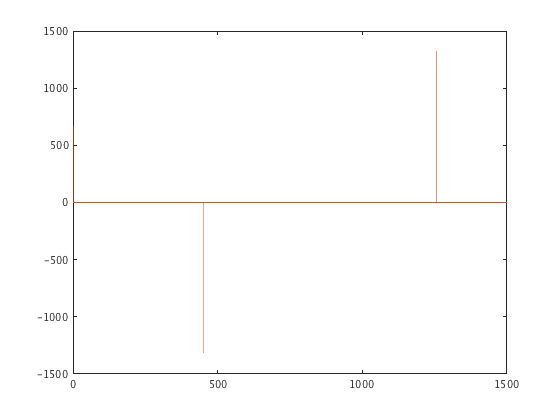

plot(t, y)

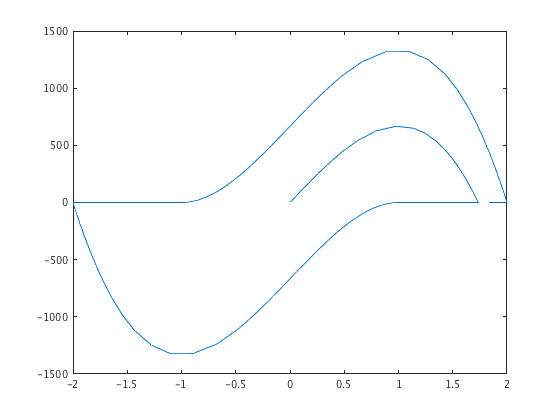

plot(y(:,1), y(:,2))

Without a left hand side the solution is plotted as it is computed. This shows how `ode45` struggles...

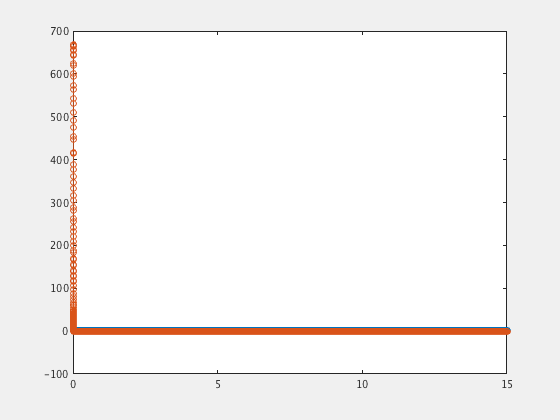

ode45(@(t,y)vdpparams(t,y,1000), [0,15], [0;1], op)

...whereas `ode15s` breezes along and clearly uses much fewer steps with larger step size.

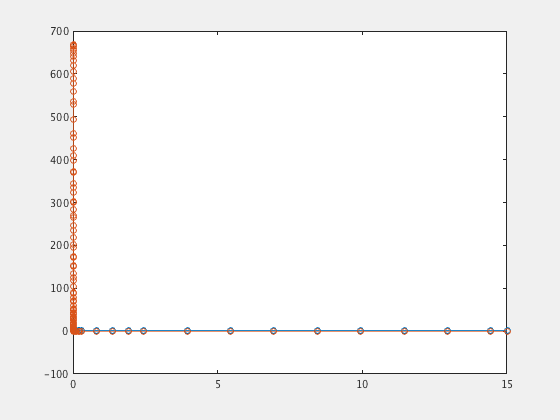

ode15s(@(t,y)vdpparams(t,y,1000), [0,15], [0;1], op)

## OutputFcn and Events

Setting the option `OutputFcn` to `odephas2` plots the solution in phase space.

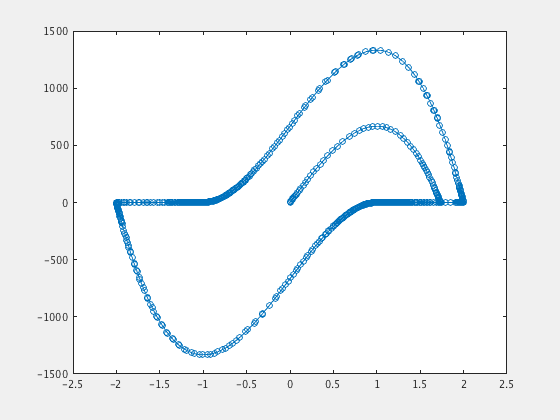

op = odeset(op, 'OutputFcn', 'odephas2');
[t, y] = ode15s(@(t,y)vdpparams(t,y,1000), [0,3000], [0;1], op);

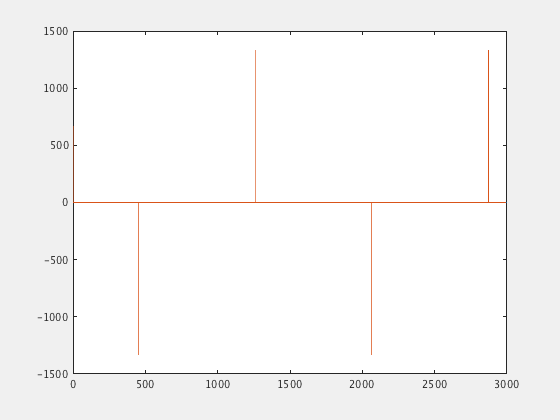

plot(t, y)

Here we are modelling the parabolic movement of a thrown ball. The ball is thrown upwards from the origin with an initial velocity of 20. When does the ball hit the origin? We'll set the option `Events` with `odeset`. The function `collision` tells the solver that it should stop solving the problem (`isterminal = 1`) when the ball hits the origin (`y(1) = 0` ) and is coming downwards (`direction = -1`). `te` gives the time interval between events. If there are more events (isterminal = 0) `te` will consist of the time intervals between adjacent events.

`function [value,isterminal,direction] = collision(t,y)`

`value = y(1);`

`isterminal = 1;`

`direction = -1;`

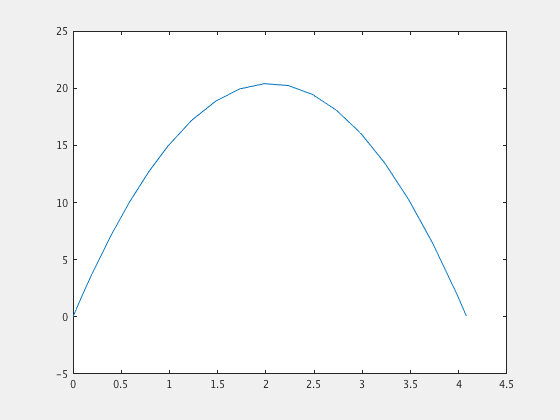

yball = @(t,y)  [y(2);-9.8];
op = odeset('Events', @collision);
[t,y,te,ye,ie] = ode45(yball,[0, 10],[0;20],op);
plot(t, y(:,1));

te

te = 4.0816

function [value,isterminal,direction] = collision(~, y)
    value = y(1);
    isterminal = 1;
    direction = -1;
end